meta_statistic_figures;

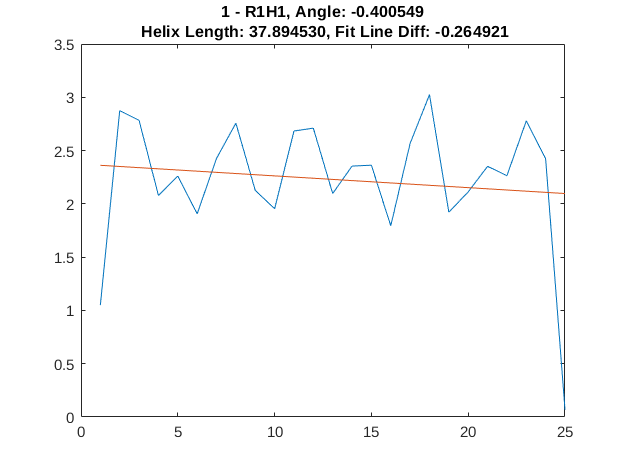

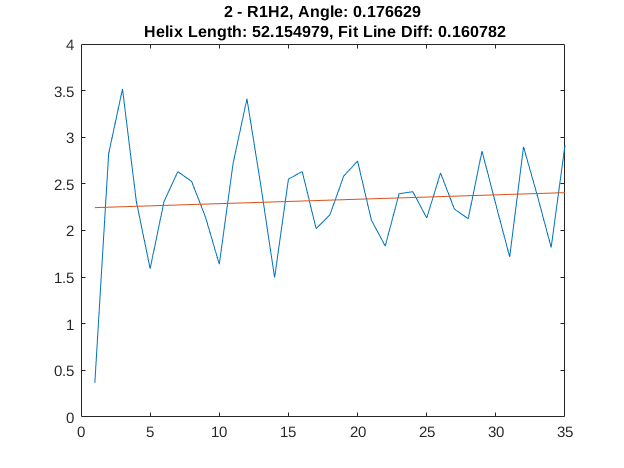

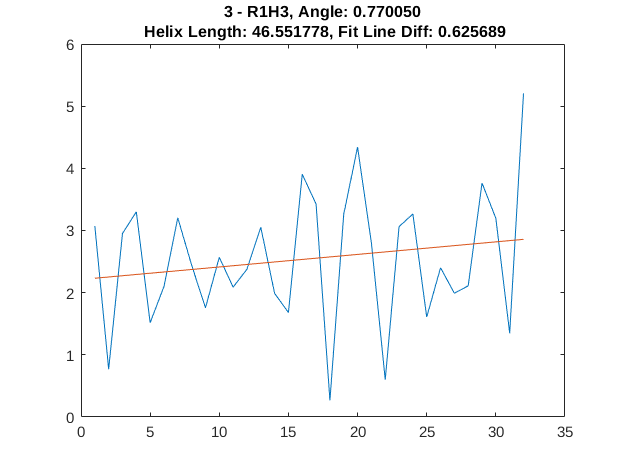

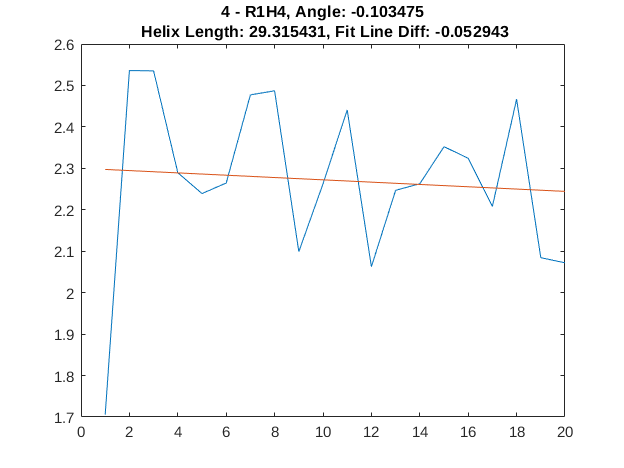

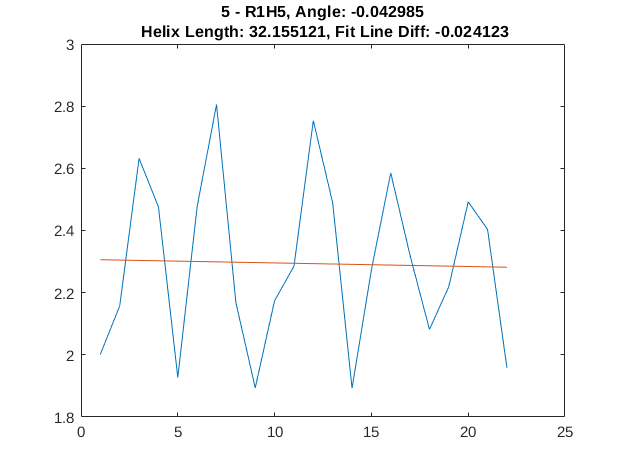

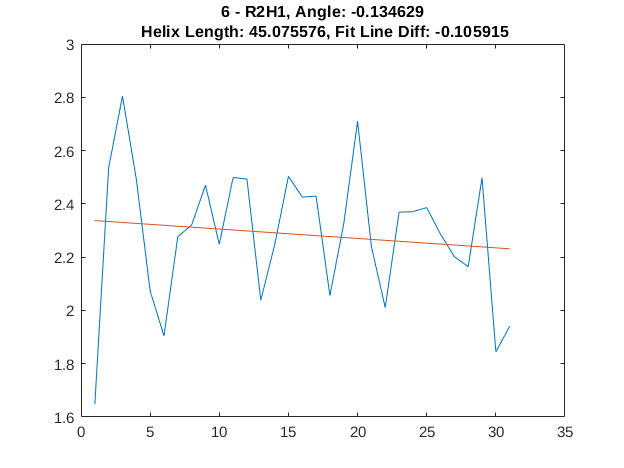

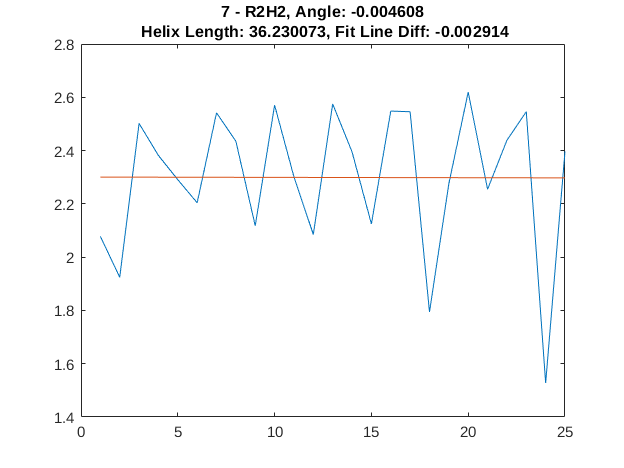

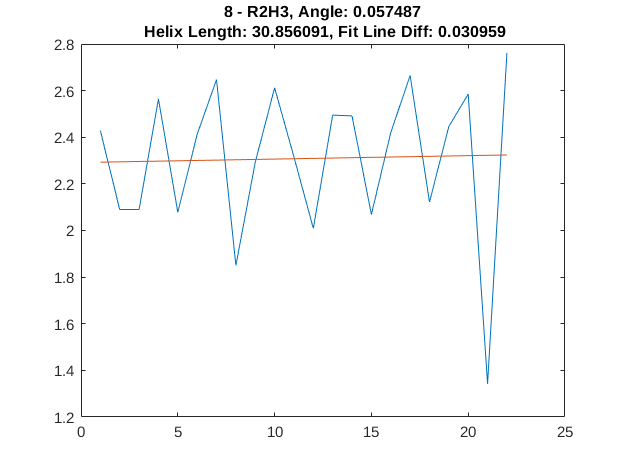

for i = 1:length(helix_statistics_data)
    fig = figure();
    plot(1:length(helix_statistics_data(i).distances), helix_statistics_data(i).distances)
    title(sprintf("%d - R%dH%d, Angle: %f\n Helix Length: %f, Fit Line Diff: %f", i, helix_statistics_data(i).domain_index, helix_statistics_data(i).helix_index, helix_statistics_data(i).fit_line_angle_d, helix_statistics_data(i).helix_length, helix_statistics_data(i).fit_line_last - helix_statistics_data(i).fit_line_first));
    hold(fig.CurrentAxes, 'on');
    plot(fig.CurrentAxes,1:length(helix_statistics_data(i).distances), helix_statistics_data(i).fit_line)
    hold(fig.CurrentAxes, 'off');
end

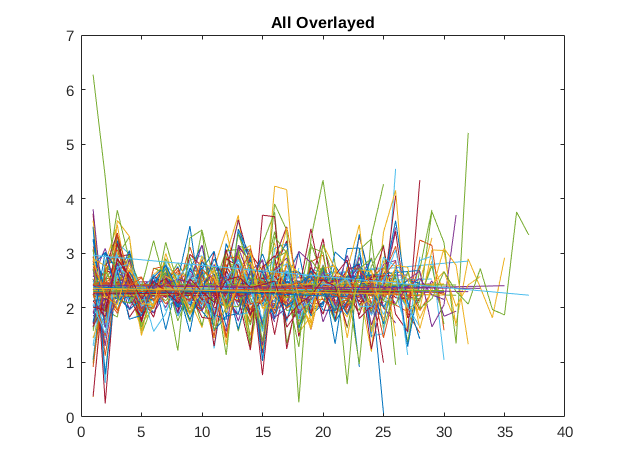

fig = figure();
plot(1:length(helix_statistics_data(1).distances), helix_statistics_data(1).distances);
title("All Overlayed");
hold(fig.CurrentAxes, 'on');
plot(fig.CurrentAxes,1:length(helix_statistics_data(1).distances), helix_statistics_data(1).fit_line)
for i = 2:length(helix_statistics_data)
    plot(fig.CurrentAxes, 1:length(helix_statistics_data(i).distances), helix_statistics_data(i).distances)
    plot(fig.CurrentAxes, 1:length(helix_statistics_data(i).distances), helix_statistics_data(i).fit_line)
end
hold(fig.CurrentAxes, 'off');

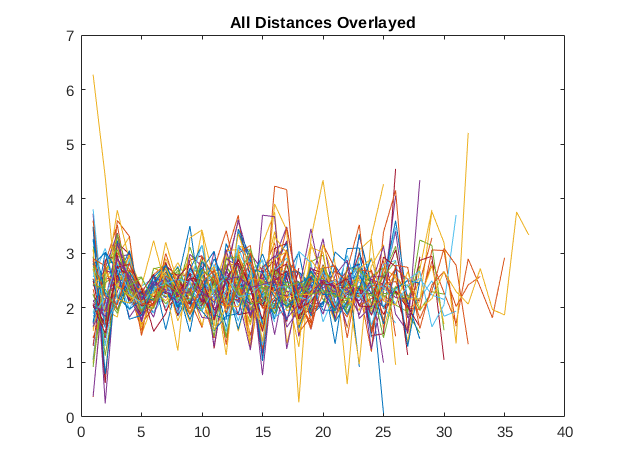

fig = figure();
plot(1:length(helix_statistics_data(1).distances), helix_statistics_data(1).distances);
title("All Distances Overlayed");
hold(fig.CurrentAxes, 'on');
% plot(fig.CurrentAxes,1:length(helix_statistics_data(1).distances), helix_statistics_data(1).fit_line)
for i = 2:length(helix_statistics_data)
    plot(fig.CurrentAxes, 1:length(helix_statistics_data(i).distances), helix_statistics_data(i).distances)
%     plot(fig.CurrentAxes, 1:length(helix_statistics_data(i).distances), helix_statistics_data(i).fit_line)
end
hold(fig.CurrentAxes, 'off');

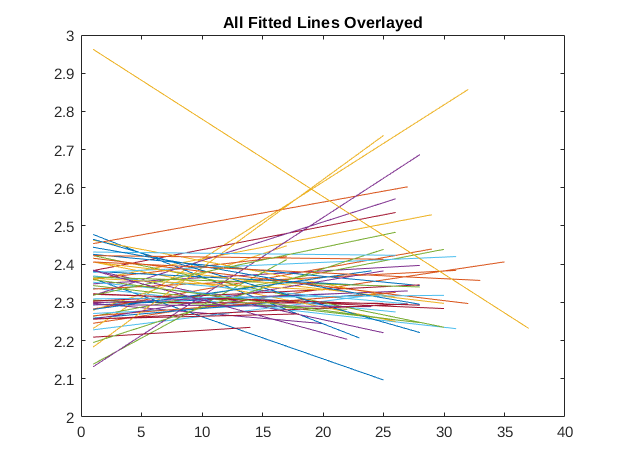

fig = figure();
% plot(1:length(helix_statistics_data(1).distances), helix_statistics_data(1).distances);
plot(1:length(helix_statistics_data(1).distances), helix_statistics_data(1).fit_line)
title("All Fitted Lines Overlayed");
hold(fig.CurrentAxes, 'on');
for i = 2:length(helix_statistics_data)
%     plot(fig.CurrentAxes, 1:length(helix_statistics_data(i).distances), helix_statistics_data(i).distances)
    plot(fig.CurrentAxes, 1:length(helix_statistics_data(i).distances), helix_statistics_data(i).fit_line)
end
hold(fig.CurrentAxes, 'off');

Normalised Angles of Fitted line: 

Min: -0.855636
Max: 0.883673
Mean: 0.034970
Standard Deviation: 0.290601

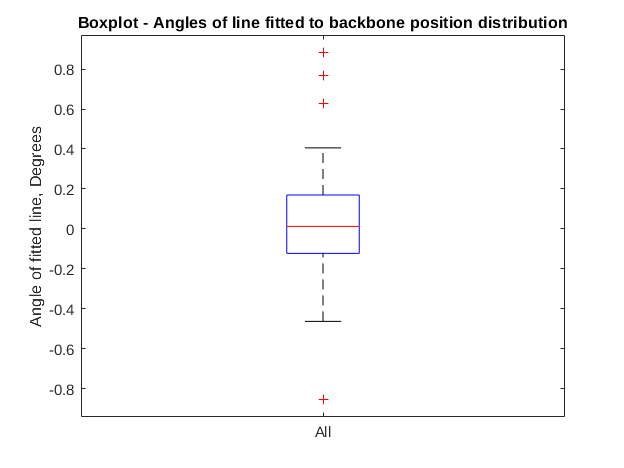

fitted_angles = [helix_statistics_data.fit_line_angle_d]';

% disp(horzcat((1:61)',fitted_angles));
fitted_angles_mean = mean(fitted_angles);
fitted_angles_sd = std(fitted_angles - fitted_angles_mean);
fitted_angles_min = min(fitted_angles);
fitted_angles_max = max(fitted_angles);
fprintf("Normalised Angles of Fitted line: ");
fprintf("Min: %f\nMax: %f\nMean: %f\nStandard Deviation: %f", fitted_angles_min, fitted_angles_max, fitted_angles_mean, fitted_angles_sd);
test = boxplot(fitted_angles, 'Labels', "All");
ylabel("Angle of fitted line, Degrees");
title("Boxplot - Angles of line fitted to backbone position distribution");
print('backbone-skew-boxplot', '-dpng', '-r150');

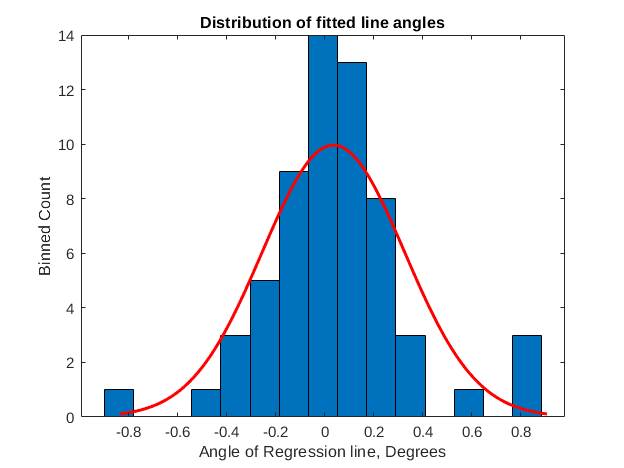

histfit(fitted_angles, 15);
title('Distribution of fitted line angles');
ylabel('Binned Count');
xlabel('Angle of Regression line, Degrees');
print('backbone-skew-histogram', '-dpng', '-r150');